# My datastore

clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data', 'raw');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");
raw_images = readall(imds);

### Label data 

Get label from filename

imds.Labels = char(imds.Labels) % turn labes to char

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Prepoznavanje oblika\Glavni domaci\Assignment 1\data\raw\bazaA001.bmp';
                              ' ...\Prepoznavanje oblika\Glavni domaci\Assignment 1\data\raw\bazaA002.bmp';
                              ' ...\Prepoznavanje oblika\Glavni domaci\Assignment 1\data\raw\bazaA003.bmp'
                               ... and 597 more
                              }
                     Folders: {
                              ' ...\Predmeti\Prepoznavanje oblika\Glavni domaci\Assignment 1\data\raw'
                              }
                      Labels: {'raw'; 'raw'; 'raw' ... and 597 more}
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                   

N = length(imds.Files);
for i = 1:N
    label = imds.Files{i}(length(folder_name) + 6);
    imds.Labels{i} = label;
end


### Display raw images

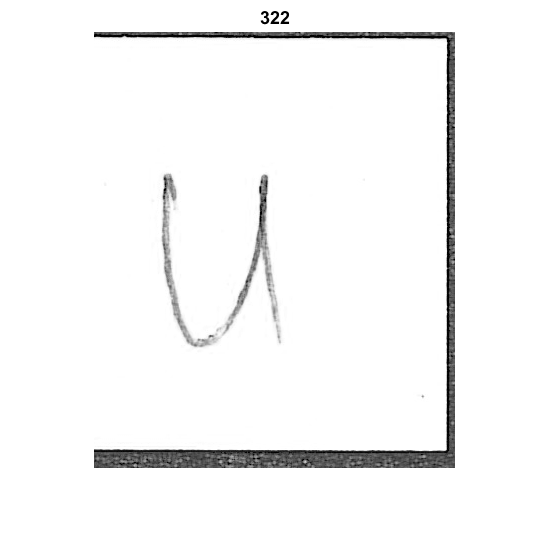

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(raw_images{rand_int})
    title(rand_int)
end

## Preprocessing images

bin_threshold = 0.9;
target_size = [224,224];

preprocessed_imds = transform(imds, @(x) imresize(x, target_size));
% gaussian filter?
preprocessed_imds = transform(preprocessed_imds, @(x) binarization(x, bin_threshold));
% median filter?
preprocessed_imds = transform(preprocessed_imds, @edge_removal);



preprocessed_images = my_readall(preprocessed_imds, N);

### Display preprocessed images

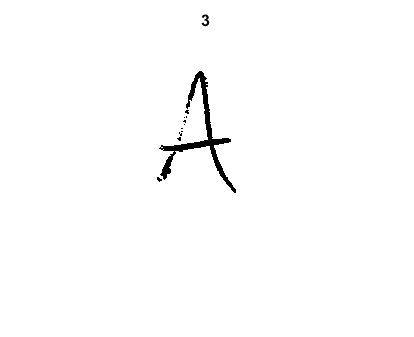

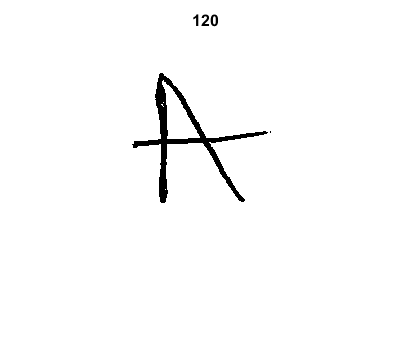

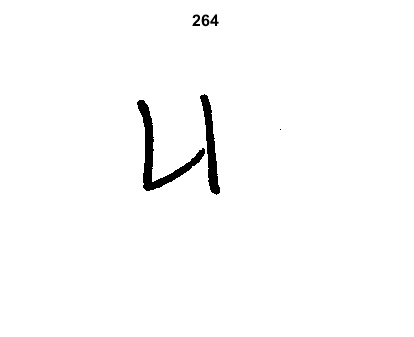

for i=1:3
    figure();
    rand_int = randi(length(imds.Files));
    imshow(preprocessed_images{rand_int})
    title(rand_int)
end

## Dividing the dataset

### Shuffling the dataset

preprocessed_imds = shuffle(preprocessed_imds);
preprocessed_images = my_readall(preprocessed_imds, N);
preprocessed_imds.UnderlyingDatastore.Labels{1:5}

ans = 'O'

ans = 'O'

ans = 'E'

ans = 'U'

ans = 'U'

### Dividing the dataset into training and testing

partition_index = round(N * 0.7);

training_imds = subset(preprocessed_imds, 1:partition_index);
testing_imds = subset(preprocessed_imds, partition_index + 1 :N);